clear; close all; clc;
load("DREAMER.mat");

EEG_SamplingRate = DREAMER.EEG_SamplingRate;  % 128Hz
ch_labels = {'AF3', 'F7', 'F3', 'FC5', 'T7', 'P7', 'O1', 'O2', 'P8', 'T8', 'FC6', 'F4', 'F8', 'AF4'};

all_EEG_data = {};
all_labels = [];

% 데이터 전처리 (BPF, CAR)
fs = EEG_SamplingRate;
low_cutoff = 4;
high_cutoff = 30;

d = designfilt('bandpassiir', 'FilterOrder', 4, ...
    'HalfPowerFrequency1', low_cutoff, 'HalfPowerFrequency2', high_cutoff, ...
    'SampleRate', fs);

for subj = 1:DREAMER.noOfSubjects
    for clip = 1:DREAMER.noOfVideoSequences
        EEG_data = DREAMER.Data{subj}.EEG.stimuli{clip};

        filtered_EEG_data = filtfilt(d, EEG_data);

        mean_data = mean(filtered_EEG_data, 2); 
        EEG_data_CAR = filtered_EEG_data - mean_data;

        all_EEG_data{end+1} = EEG_data_CAR;

        valence = DREAMER.Data{subj}.ScoreValence(clip);
        arousal = DREAMER.Data{subj}.ScoreArousal(clip);
        dominance = DREAMER.Data{subj}.ScoreDominance(clip);
        
        all_labels = [all_labels; valence, arousal, dominance];
    end
end

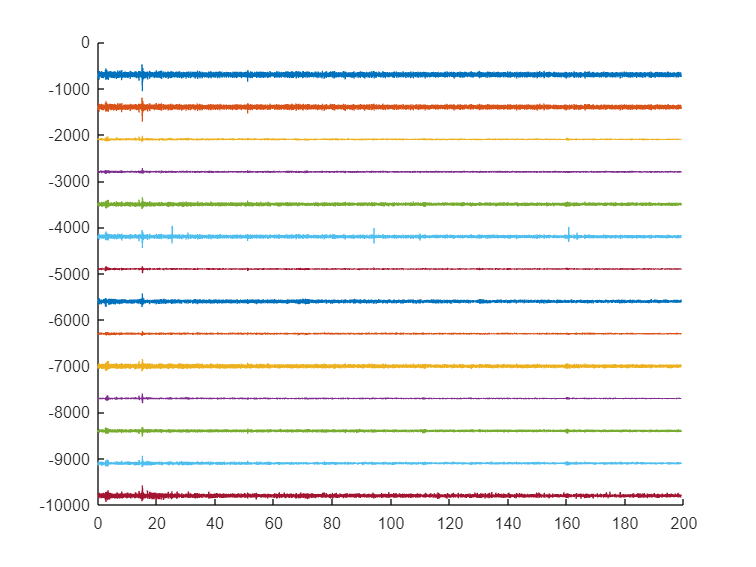

% 데이터 플롯
first_trial_data = all_EEG_data{1};

[num_time_points, num_channels] = size(first_trial_data);

time = (0:num_time_points-1) / fs;

figure;
hold on;
offset = 700;
for ch = 1:num_channels
    plot(time, first_trial_data(:, ch) - ch * offset);
end
hold off;

% 특징 추출 (PSD)
fs = 128;
win_length = 256;
overlap = 128;

theta_band = [4 8];
alpha_band = [8 13];
beta_band = [13 30];

all_psd_features = {};

for trial_idx = 1:length(all_EEG_data)
    EEG_data = all_EEG_data{trial_idx};
    [num_time_points, num_channels] = size(EEG_data);
    
    psd_features = [];
    
    for ch = 1:num_channels
        [pxx, f] = pwelch(EEG_data(:, ch), win_length, overlap, [], fs);
        
        theta_power = bandpower(pxx, f, theta_band, 'psd');
        alpha_power = bandpower(pxx, f, alpha_band, 'psd');
        beta_power = bandpower(pxx, f, beta_band, 'psd');
        
        psd_features = [psd_features, log(theta_power), log(alpha_power), log(beta_power)];
    end

    all_psd_features{end+1} = psd_features;
    fprintf('Trial %d 분석 완료\n', trial_idx);
end

Trial 1 분석 완료
Trial 2 분석 완료
Trial 3 분석 완료
Trial 4 분석 완료
Trial 5 분석 완료
Trial 6 분석 완료
Trial 7 분석 완료
Trial 8 분석 완료
Trial 9 분석 완료
Trial 10 분석 완료
Trial 11 분석 완료
Trial 12 분석 완료
Trial 13 분석 완료
Trial 14 분석 완료
Trial 15 분석 완료
Trial 16 분석 완료
Trial 17 분석 완료
Trial 18 분석 완료
Trial 19 분석 완료
Trial 20 분석 완료
Trial 21 분석 완료
Trial 22 분석 완료
Trial 23 분석 완료
Trial 24 분석 완료
Trial 25 분석 완료
Trial 26 분석 완료
Trial 27 분석 완료
Trial 28 분석 완료
Trial 29 분석 완료
Trial 30 분석 완료
Trial 31 분석 완료
Trial 32 분석 완료
Trial 33 분석 완료
Trial 34 분석 완료
Trial 35 분석 완료
Trial 36 분석 완료
Trial 37 분석 완료
Trial 38 분석 완료
Trial 39 분석 완료
Trial 40 분석 완료
Trial 41 분석 완료
Trial 42 분석 완료
Trial 43 분석 완료
Trial 44 분석 완료
Trial 45 분석 완료
Trial 46 분석 완료
Trial 47 분석 완료
Trial 48 분석 완료
Trial 49 분석 완료
Trial 50 분석 완료
Trial 51 분석 완료
Trial 52 분석 완료
Trial 53 분석 완료
Trial 54 분석 완료
Trial 55 분석 완료
Trial 56 분석 완료
Trial 57 분석 완료
Trial 58 분석 완료
Trial 59 분석 완료
Trial 60 분석 완료
Trial 61 분석 완료
Trial 62 분석 완료
Trial 63 분석 완료
Trial 64 분석 완료
Trial 65 분석 완료
Trial 66 분석 완료
Trial 67 분석 완료
Tria

save('all_psd_features.mat', 'all_psd_features');

% 모든 특징과 레이블 매트릭스 생성
X = cell2mat(all_psd_features');
Y = double(all_labels);  % 응답 변수를 double로 변환

% 데이터 정규화
X_mean = mean(X);
X_std = std(X);
X_normalized = (X - X_mean) ./ X_std;

% K-겹 교차 검증을 통한 모델 학습
k = 5; % K-겹 설정
cv = cvpartition(size(X_normalized, 1), 'KFold', k);

% Valence 모델 학습
mdl_valence = fitrensemble(X_normalized, Y(:, 1), 'Method', 'Bag', 'NumLearningCycles', 100, ...
                   'Learners', 'Tree', 'CrossVal', 'on', 'KFold', k);

% Arousal 모델 학습
mdl_arousal = fitrensemble(X_normalized, Y(:, 2), 'Method', 'Bag', 'NumLearningCycles', 100, ...
                   'Learners', 'Tree', 'CrossVal', 'on', 'KFold', k);

% Dominance 모델 학습
mdl_dominance = fitrensemble(X_normalized, Y(:, 3), 'Method', 'Bag', 'NumLearningCycles', 100, ...
                   'Learners', 'Tree', 'CrossVal', 'on', 'KFold', k);

               
% 모델 성능 평가
loss_valence = kfoldLoss(mdl_valence);
loss_arousal = kfoldLoss(mdl_arousal);
loss_dominance = kfoldLoss(mdl_dominance);

disp(['K-겹 교차 검증 평균 손실 (Valence): ', num2str(loss_valence)]);

K-겹 교차 검증 평균 손실 (Valence): 1.848


disp(['K-겹 교차 검증 평균 손실 (Arousal): ', num2str(loss_arousal)]);

K-겹 교차 검증 평균 손실 (Arousal): 1.1674


disp(['K-겹 교차 검증 평균 손실 (Dominance): ', num2str(loss_dominance)]);

K-겹 교차 검증 평균 손실 (Dominance): 1.1799



% 예측
Y_pred_valence = kfoldPredict(mdl_valence);
Y_pred_arousal = kfoldPredict(mdl_arousal);
Y_pred_dominance = kfoldPredict(mdl_dominance);

% 성능 평가
mse_valence = mean((Y(:, 1) - Y_pred_valence).^2);
mse_arousal = mean((Y(:, 2) - Y_pred_arousal).^2);
mse_dominance = mean((Y(:, 3) - Y_pred_dominance).^2);

r2_valence = 1 - sum((Y(:, 1) - Y_pred_valence).^2) / sum((Y(:, 1) - mean(Y(:, 1))).^2);
r2_arousal = 1 - sum((Y(:, 2) - Y_pred_arousal).^2) / sum((Y(:, 2) - mean(Y(:, 2))).^2);
r2_dominance = 1 - sum((Y(:, 3) - Y_pred_dominance).^2) / sum((Y(:, 3) - mean(Y(:, 3))).^2);

% 결과 출력
disp('Valence 예측 결과:');

Valence 예측 결과:


fprintf('MSE: %.4f, R²: %.4f\n', mse_valence, r2_valence);

MSE: 1.8480, R²: -0.0640



disp('Arousal 예측 결과:');

Arousal 예측 결과:


fprintf('MSE: %.4f, R²: %.4f\n', mse_arousal, r2_arousal);

MSE: 1.1674, R²: -0.0002



disp('Dominance 예측 결과:');

Dominance 예측 결과:


fprintf('MSE: %.4f, R²: %.4f\n', mse_dominance, r2_dominance);

MSE: 1.1799, R²: -0.0328
